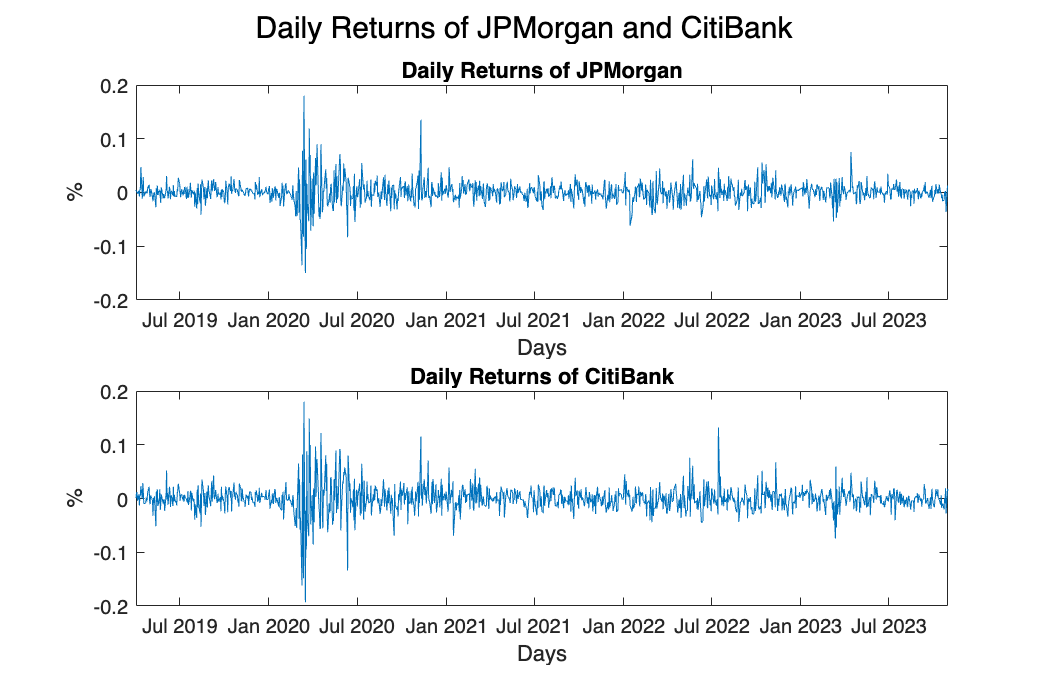

        %% Q.6 - HW3 %%
% tidying up
clc;    % clear the command window
clear;  % clear the workspace
close all; % close all opened figures

% Load the data
data = readtimetable('Banks.xlsx');

% Plot JPM time series
x0=500; y0=500; width=1000; height=650;
figure('Position',[x0,y0,width,height])

% Plot JPMorgan time series
subplot(2, 1, 1)
plot(data.Date(2:end), data.JPM(2:end))
title('Daily Returns of JPMorgan')
ylabel('%')
xlabel('Days')
xlim tight

% Plot Citibank time series
subplot(2, 1, 2)
plot(data.Date(2:end), data.C(2:end))
title('Daily Returns of CitiBank')
ylabel('%')
xlabel('Days')
xlim tight

sgtitle('Daily Returns of JPMorgan and CitiBank'); % Add a common title


% Sample correlations, lag=20
sample_correlation = corr(data.JPM(2:end), data.C(2:end))

sample_correlation = 0.8687

disp(['Sample correlation between JPMorgan and Citibank: ', num2str(sample_correlation)]);

Sample correlation between JPMorgan and Citibank: 0.86871



% Rolling window correlation (n=60) 
n = 60; % window size
rolling_corr = zeros(length(data.JPM) - n + 1, 1);

for t = n:length(data.JPM(193:end))
    rolling_corr(t - n + 1) = corr(data.JPM(t-n+1:t), data.C(t-n+1:t));
end
disp(mean(rolling_corr));

    0.6947



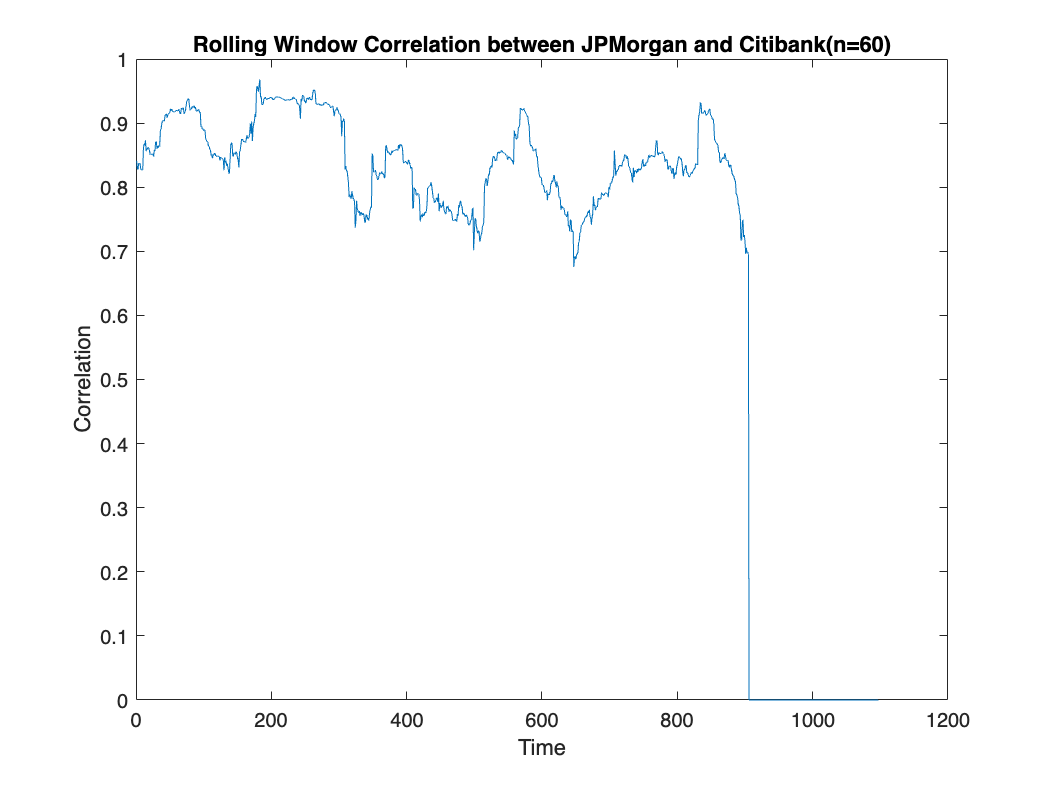


% Plot the rolling correlation
figure;
plot(rolling_corr);
title('Rolling Window Correlation between JPMorgan and Citibank(n=60)');
xlabel('Time');
ylabel('Correlation');


% Rolling window correlation (n=180)
n = 180; % window size
rolling_corr = zeros(length(data.JPM) - n + 1, 1);

for t = n:length(data.JPM(193:end))
    rolling_corr(t - n + 1) = corr(data.JPM(t-n+1:t), data.C(t-n+1:t));
end
disp(mean(rolling_corr));

    0.6805



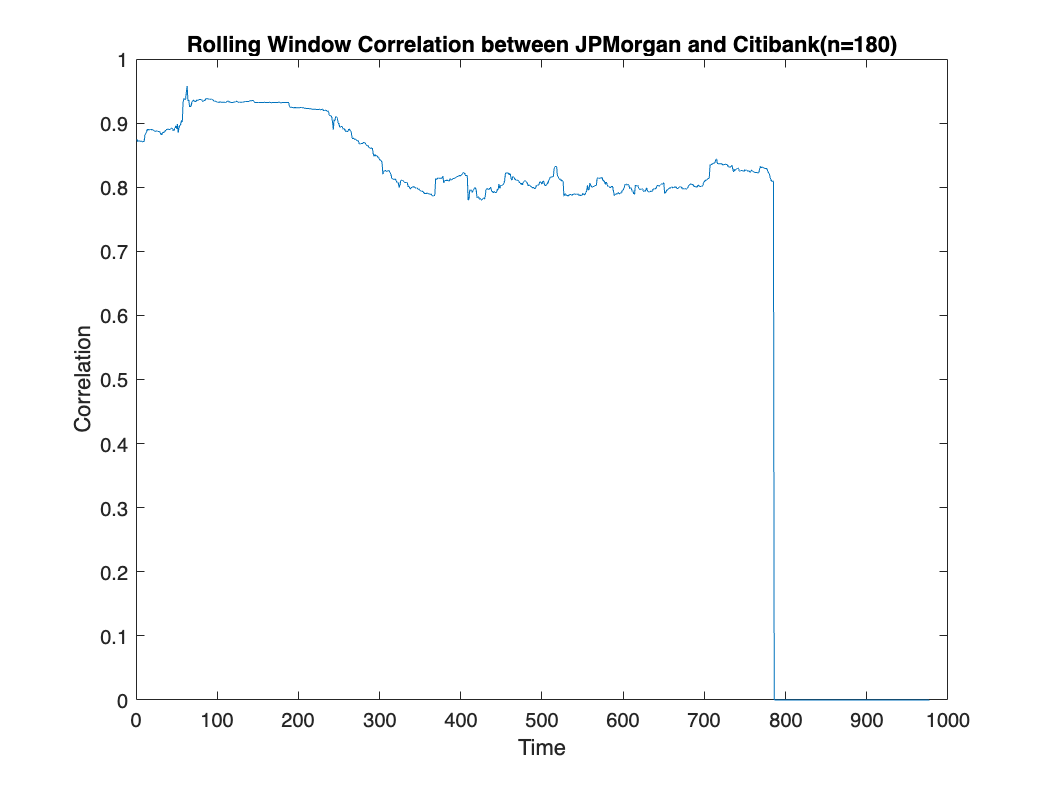


% Plot the rolling correlation
figure;
plot(rolling_corr);
title('Rolling Window Correlation between JPMorgan and Citibank(n=180)');
xlabel('Time');
ylabel('Correlation');


% Conclusion to (6.b) and (6.c) is that rolling window correlation
% estimates are lower compared to sample correlation. That could be mainly
% based on the fact that rolling window correlation takes most recent data,
% while disgarding the older observations.
% Furthermore, it is observed that rolling window correlation is sensitive
% to the choice of window length.

% Sample correlation estimate of "0.8687" is relatively high, suggesting a
% high correlation between these two bank returns in this sample period.
